clearvars
close all
clc

tt = readtable('input_data\08_00-10_00-non-duplicated.csv');

tt.Var1 = [];
tt.Unnamed_0 =[];
tt.arac_id = categorical(tt.arac_id); %make vehicle ids categorical data type to efficiency
tt.tarih = [];
tt.UNIX_TIMESTAMP = [];
tt.Properties.VariableNames{4} = 'time';
tt=sortrows(tt,{'arac_id','time'});

tt.time_num=zeros(size(tt,1),1); %create cloumn
func_numerator = @(x) {transpose(1:1:length(x))}; 

[G] = findgroups(tt.arac_id); %category indexes
tt.time_num = uint64(cell2mat(splitapply(func_numerator,G,G))); %table must be ordered to assign time_numerator correctly

n_duplicates = size(tt(:,2:end),1) - size(unique(tt(:,{'arac_id','time'})),1)

n_duplicates = 0

osrm_data_sp = load('output_data\osrm_output_with_speed.mat').out;
aug_data = load('output_data\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1)

ans = 114587

sum(filter)

ans = 2669


aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1)

ans = 114833

sum(filter)

ans = 3666

selecte_vehicle_id = tt(tt.arac_id == "1e11q58",:)

selecte_vehicle_id = 49×5 table
    arac_id    longitude    latitude           time            time_num
    _______    _________    ________    ___________________    ________

    1e11q58     32.711       39.905     2019-11-18 08:09:50        1   
    1e11q58      32.71       39.905     2019-11-18 08:10:06        2   
    1e11q58      32.71       39.905     2019-11-18 08:10:09        3   
    1e11q58      32.71       39.905     2019-11-18 08:10:12        4   
    1e11q58     32.712       39.906     2019-11-18 08:10:21        5   
    1e11q58     32.714       39.906     2019-11-18 08:10:31        6   
    1e11q58     32.717       39.906     2019-11-18 08:10:41        7   
    1e11q58     32.719       39.906     2019-11-18 08:10:51        8   
    1e11q58     32.721       39.906     2019-11-18 08:11:01        9   
    1

osrm_data_sp = osrm_data_sp(~isnan(osrm_data_sp.speed),:);



a = findgroups(osrm_data_sp(:,{'arac_id','route_id'}));

osrm_data_sp.clean_speed = zeros(size(osrm_data_sp,1),1);
osrm_data_sp.raw_acc = zeros(size(osrm_data_sp,1),1);
osrm_data_sp.acc_smoothed = zeros(size(osrm_data_sp,1),1);
osrm_data_sp.smooth_speed_acc = zeros(size(osrm_data_sp,1),1);

% split apply?
for i=1:1:max(a)
    aux_index = a == i;
    osrm_data_sp.clean_speed(aux_index) = smoothdata(osrm_data_sp.speed(aux_index),'rlowess',5);
    osrm_data_sp.raw_acc(aux_index) = (([diff(osrm_data_sp.speed(aux_index));NaN] * 1000 / 3600) ./ (osrm_data_sp.time_distance(aux_index)* 3600));
    osrm_data_sp.smooth_speed_acc(aux_index) = (([diff(osrm_data_sp.clean_speed(aux_index));NaN] * 1000 / 3600) ./ (osrm_data_sp.time_distance(aux_index)* 3600));
    osrm_data_sp.acc_smoothed(aux_index) = smoothdata(osrm_data_sp.raw_acc(aux_index),'rlowess',5);
end


osrm_data_sp.delta_v =  osrm_data_sp.speed - osrm_data_sp.clean_speed;
osrm_data_sp.delta_v_perc =  100 *  abs(osrm_data_sp.delta_v) ./ osrm_data_sp.clean_speed;
osrm_data_sp.delta_a =  osrm_data_sp.raw_acc - osrm_data_sp.smooth_speed_acc;
osrm_data_sp.delta_a_perc =  100 *  abs(osrm_data_sp.delta_a) ./ osrm_data_sp.smooth_speed_acc;


* = robus lowess operations

rule 1 = speed > 200

rule 2 = abs(100 * (speed - *speed) / *speed) > 100

rule 3 = abs(raw_acc) > 10

rule 4 = raw_acc - acc(*speed) > 3

osrm_data_sp.rule1 = false(size(osrm_data_sp,1),1);
osrm_data_sp.rule2 = false(size(osrm_data_sp,1),1);
osrm_data_sp.rule3 = false(size(osrm_data_sp,1),1);
osrm_data_sp.rule4 = false(size(osrm_data_sp,1),1);

osrm_data_sp.rule1(osrm_data_sp.speed > 200) = true;
osrm_data_sp.rule2(abs(osrm_data_sp.delta_v_perc) > 100) = true;
osrm_data_sp.rule3(abs(osrm_data_sp.raw_acc)> 10) = true;
osrm_data_sp.rule4(abs(osrm_data_sp.delta_a) > 3) = true;

osrm_data_sp.filter2 = osrm_data_sp.rule1 | osrm_data_sp.rule2 | osrm_data_sp.rule3 | osrm_data_sp.rule4;

sum(osrm_data_sp.filter2)

ans = 495


osrm_data_sp.new_speed = osrm_data_sp.speed;
osrm_data_sp.new_speed(osrm_data_sp.filter2) = osrm_data_sp.clean_speed(osrm_data_sp.filter2);

Unrecognized function or variable 'selected_data'.

'l6xs3c0l'

ans = 'l6xs3c0l'

selected_data = osrm_data_sp

selected_data = 110168×34 table
    arac_id     lon       lat              time            route_id    confidence    assos_nodes_start    assos_nodes_end                                           nodes_to_go                                           dir    segment_id    isMatchedSegments    distance_to_start_node    distance_to_end_node    distance_from_start    isUsedAug    space_distance    time_distance    speed     filter    clean_speed     raw_acc     acc_smoothed    smooth_speed_acc    delta_v     delta_v_perc     delta_a     

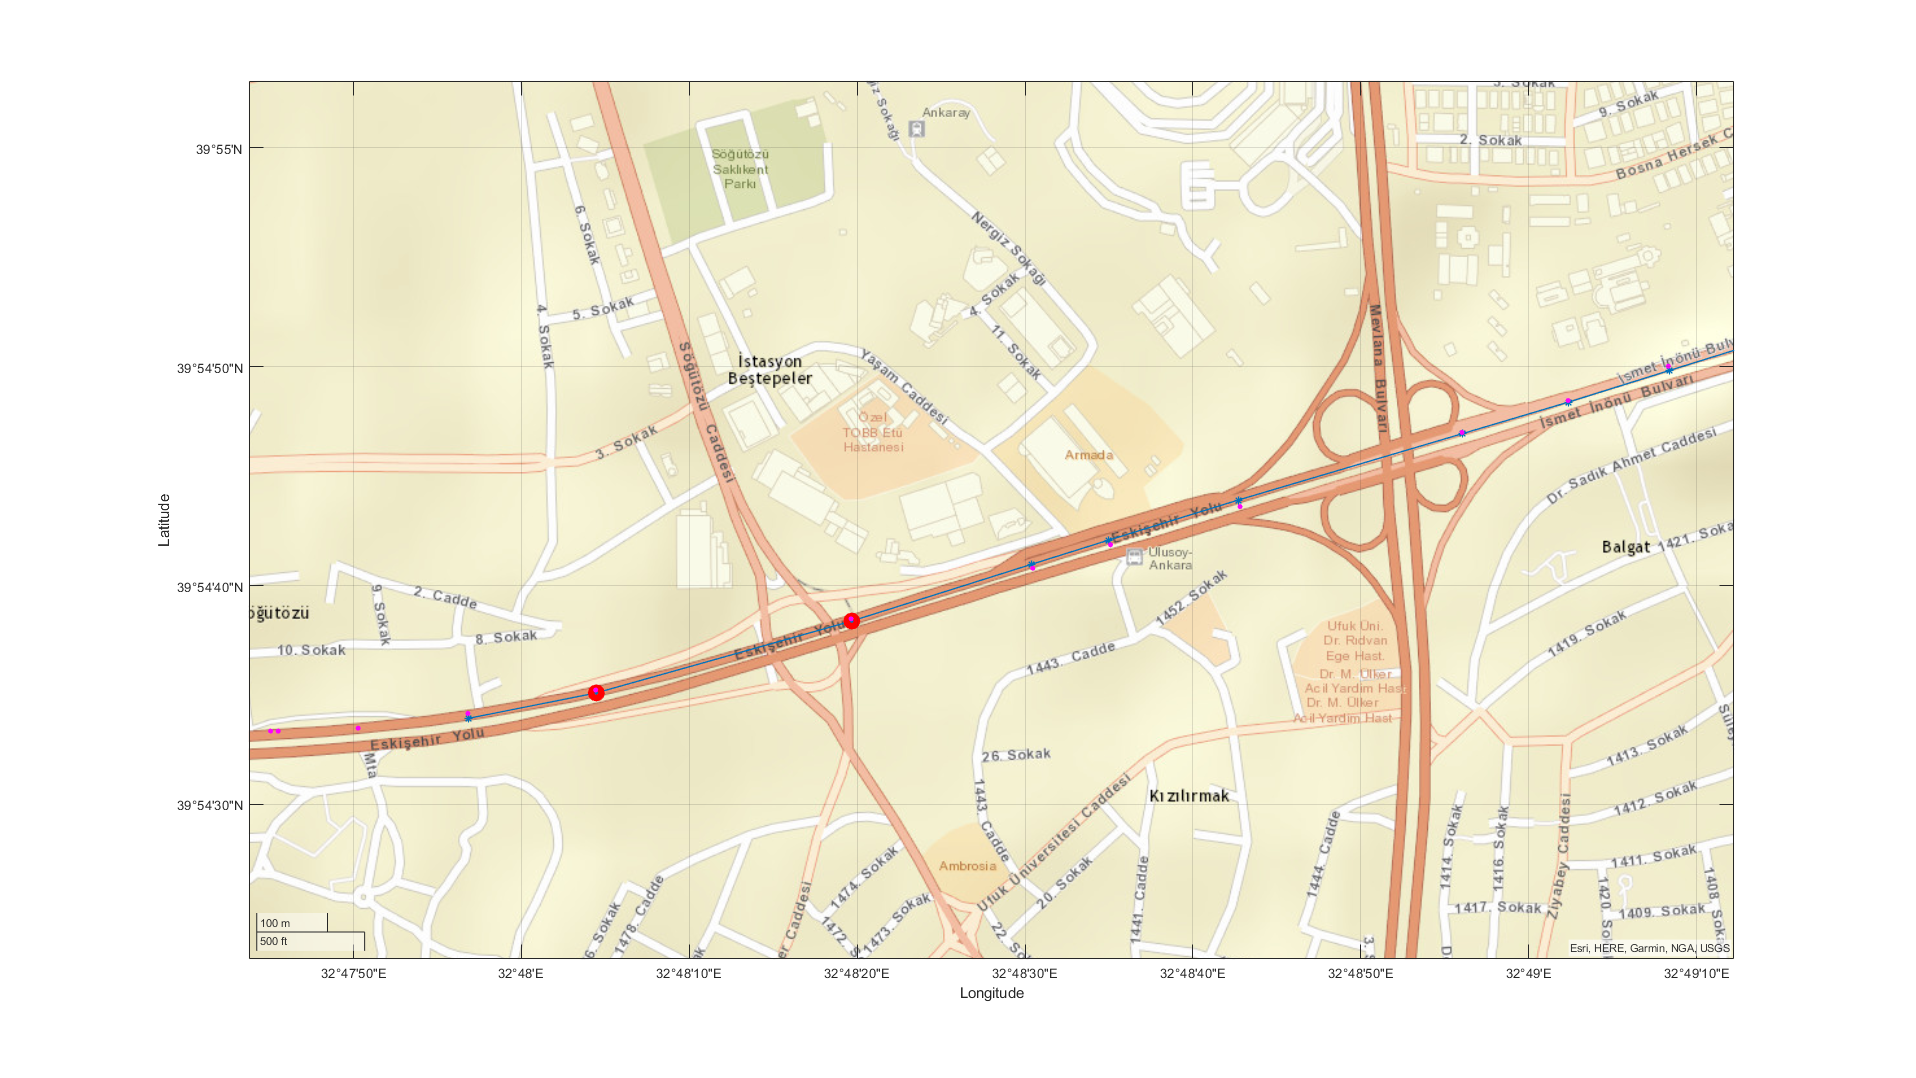

thres = 200;
selected_arac_id = 'l6xs3c0l';
selected_data(~(selected_data.arac_id == selected_arac_id),:) = [];

a = findgroups(selected_data(:,{'arac_id','route_id'}));

h = figure();

for i=1:1:max(a)
    aux_index = a == i;
    
    s1 = geoplot(selected_data.lat(aux_index),selected_data.lon(aux_index),"Marker","*","LineWidth",1);
    hold on
    s1.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(aux_index)));
    s1.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(aux_index)));
    s1.DataTipTemplate.DataTipRows(1:2)=[];
    
    s2 = geoscatter(selected_data.lat(logical(aux_index .* (selected_data.speed> thres))), selected_data.lon(logical(aux_index .* (selected_data.speed> thres))),60,'red',"LineWidth",5);
    s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(1:2)=[];
    
    
%     s2.DataTipTemplate.DataTipRows(3) = 
    
    
    
    
    % hold on
    % s2=geoscatter(T_aug.lat(loc_aug),T_aug.lon(loc_aug),120,'black');
    % s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('Time',cellstr(datestr(T_aug.time(loc_aug))));
    % hold on
    % s3=geoscatter(osm.startLat(osm.dir==1),osm.startLon(osm.dir==1),90,'s','blue'); %start
    % hold on
    % s4=geoscatter(osm.endLat(osm.dir==1),osm.endLon(osm.dir==1),15,'s','blue','filled'); %end
    % hold on
    % s5=geoscatter(osm.startLat(osm.dir==2),osm.startLon(osm.dir==2),90,'s','blue'); %start
    % hold on
    % s6=geoscatter(osm.endLat(osm.dir==2),osm.endLon(osm.dir==2),15,'s','blue','filled'); %end
    
    % legend('real','aug','segments start','segments end')
    % title(['arac id ', T_arac.arac_cats{fig_arac_id}]);
    % 
    % 
    % text(T_real.lat(loc_real),T_real.lon(loc_real),num2str(T_real.time_num(loc_real)))
    hold on
end


s3 = geoscatter(tt.latitude(tt.arac_id == selected_arac_id), tt.longitude(tt.arac_id == selected_arac_id),15,'filled','magenta',"LineWidth",0.1);
s3.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(tt.arac_id(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(tt.time(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(1:2)=[];


% alpha(s3,0.65);

geobasemap streets
set(h,'Units','normalized','Position',[0 0 1 1]);

h = figure();

selected_segments_1 = 12:19;
selected_segments_2 = 48:67;
selected_segments_3 = 171:190;

s1 = geoplot(segments.startLat(ismember(segments.segment_id, selected_segments_1)),segments.startLon(ismember(segments.segment_id, selected_segments_1)),"LineWidth",15,"Color","blue");
hold on
s2 = geoplot(segments.startLat(ismember(segments.segment_id, selected_segments_2)),segments.startLon(ismember(segments.segment_id, selected_segments_2)),"LineWidth",15,"Color","red");
hold on
s3 = geoplot(segments.startLat(ismember(segments.segment_id, selected_segments_3)),segments.startLon(ismember(segments.segment_id, selected_segments_3)),"LineWidth",15,"Color","magenta");

% ismember(segments.segment_id, [12:19])
% xlim([min(segments.startLon) max(segments.startLon)])
nlon = [min(segments.startLon) max(segments.startLon)]

nlon =    32.1415   32.8487


nlat = [min(segments.startLat) max(segments.startLat)]

nlat =    39.5748   39.9162


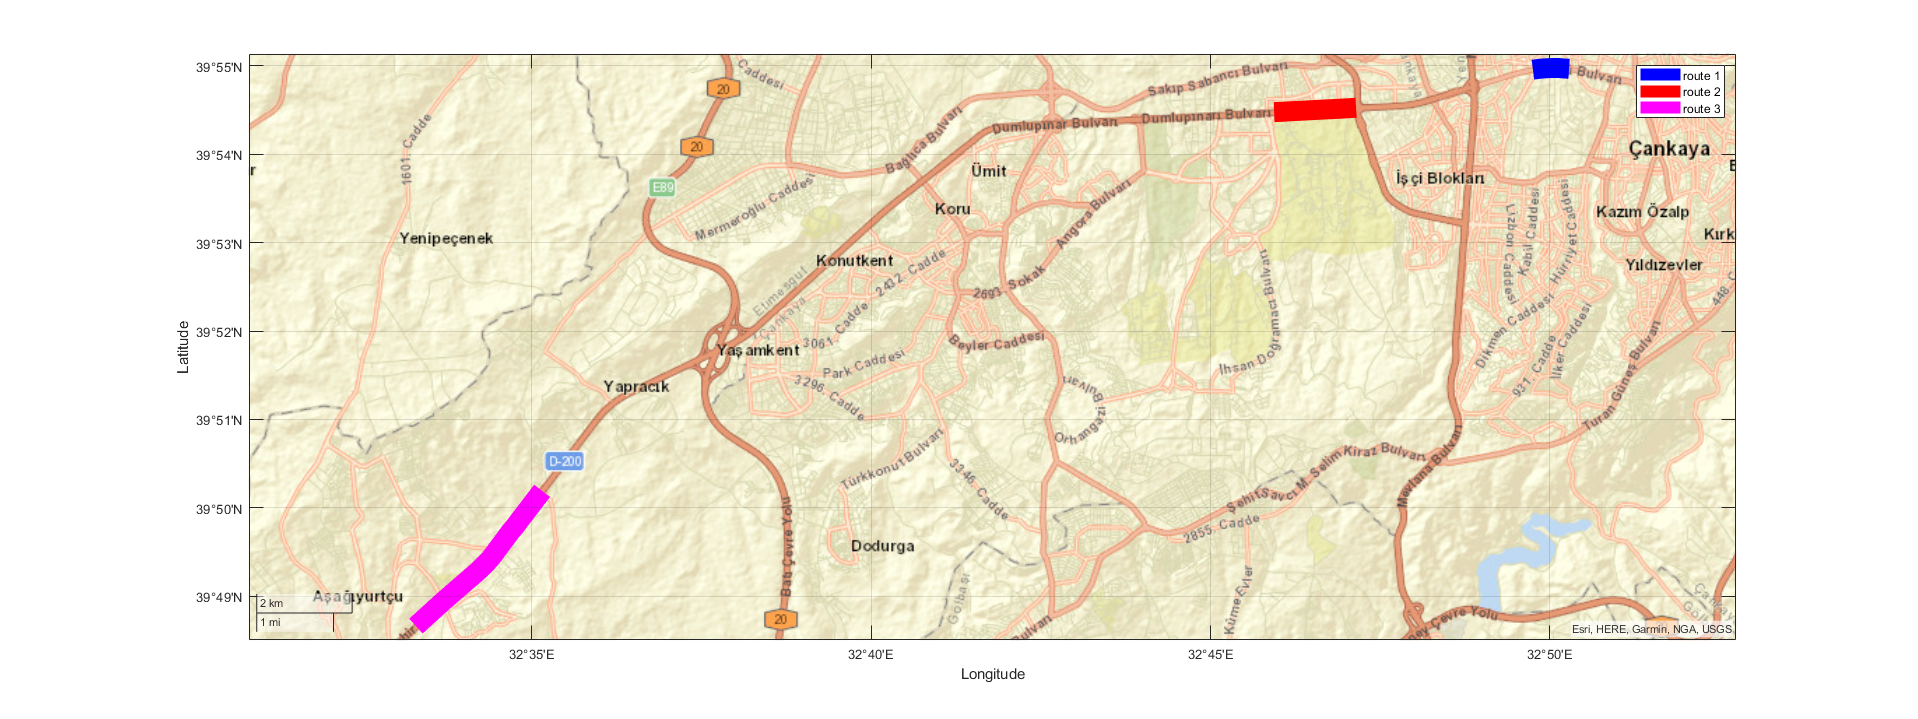


% geolimits(nlat,nlon);
legend(["route 1" , "route 2", "route 3"])
geobasemap streets
set(h,'Units','normalized','Position',[0 0 15 10]);

s1

s1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 15
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
       LatitudeData: [39.9161 39.9162 39.9162 39.9162 39.9162 39.9162 39.9161 39.9159]
      LongitudeData: [32.8380 32.8362 32.8355 32.8342 32.8335 32.8324 32.8306 32.8292]
              ZData: [1×0 double]

  Show all properties


segments

segments = 655×14 table
    segment_id    start_node     end_node     given_length    road_type    speed                             st_astext                             startLat    startLon    endLat    endLon    dir    calc_length    distance_from_start
    __________    __________    __________    ____________    _________    _____    ___________________________________________________________    ________    ________    ______    ______    ___    ___________    ___________________

         1         164555561    4

[a,b] = findgroups(osrm_data_sp.arac_id);
color_1 =  rand(length(b),3);

h = figure();
subplot(1,2,1)
scatter(osrm_data_sp.space_distance,osrm_data_sp.speed,10,color_1(a,:),'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')

subplot(1,2,2)
scatter(osrm_data_sp.space_distance(~osrm_data_sp.filter2),osrm_data_sp.speed(~osrm_data_sp.filter2),10,color_1(a(~osrm_data_sp.filter2),:),'filled')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

h = figure();
subplot(1,2,1)
scatter(osrm_data_sp.time_distance * 60 * 60,osrm_data_sp.speed,10,color_1(a,:),'filled')
xlabel('time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')
subplot(1,2,2)
scatter(osrm_data_sp.time_distance(~osrm_data_sp.filter2) * 60 * 60,osrm_data_sp.speed(~osrm_data_sp.filter2),10,color_1(a(~osrm_data_sp.filter2),:),'filled')
set(h,'Units','normalized','Position',[0 0 1 0.5]);

h = figure();
subplot(1,2,1)

scatter(osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

subplot(1,2,2)

scatter(osrm_data_sp(~osrm_data_sp.filter2,:).space_distance,osrm_data_sp(~osrm_data_sp.filter2,:).speed,10,color_1(a(~osrm_data_sp.filter2),:),'filled')

set(h,'Units','normalized','Position',[0 0 1 0.5]);

h = figure();
subplot(1,2,1)
scatter(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel(' time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

subplot(1,2,2)
scatter(osrm_data_sp(~osrm_data_sp.filter2,:).time_distance * 60 * 60,osrm_data_sp(~osrm_data_sp.filter2,:).speed,10,color_1(a(~osrm_data_sp.filter2),:),'filled')
set(h,'Units','normalized','Position',[0 0 1 0.5]);


scatter3(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel('time diff')
ylabel('space diff')
zlabel('speed')
grid on
title('MAT* dx-dt-v')


% 500 'den fazla olan datalar

thres = 200;

index = osrm_data_sp.speed > thres;
get_data = unique(osrm_data_sp(index,{'arac_id','route_id'}));

% bu dataları barındıran rotalar
% a = unique(get_data(:,));

selected_data = table;

for i = 1:1:size(get_data,1)
    index1 = osrm_data_sp.arac_id == get_data.arac_id(i);
    index2 = osrm_data_sp.route_id == get_data.route_id(i);
    index3 = logical(index1 .* index2);
    
    selected_data = vertcat(selected_data,osrm_data_sp(index3,:));
%     [b, c] = ismember(a,osrm_data_sp(:,{'arac_id','route_id'}),'rows');
end

[a,b] = groupcounts(selected_data.arac_id);

arac_info = table(b,a);
arac_info = sortrows(arac_info,'a',"descend");

head(arac_info)
% arac_info







% unique(selected_data.arac_id)
% q9oc158
% 3bx0r4x 
%      caqc481 

%      cttnol3 

%      3bx0r4x 




selected_arac_id = 'l50l3qc';
selected_data(~(selected_data.arac_id == selected_arac_id),:) = [];

a = findgroups(selected_data(:,{'arac_id','route_id'}));

h = figure();

for i=1:1:max(a)
    aux_index = a == i;
    
    s1 = geoplot(selected_data.lat(aux_index),selected_data.lon(aux_index),"Marker","*","LineWidth",1);
    hold on
    s1.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(aux_index)));
    s1.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(aux_index)));
    s1.DataTipTemplate.DataTipRows(1:2)=[];
    
    s2 = geoscatter(selected_data.lat(logical(aux_index .* (selected_data.speed> thres))), selected_data.lon(logical(aux_index .* (selected_data.speed> thres))),60,'red',"LineWidth",5);
    s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(1:2)=[];
    
    
%     s2.DataTipTemplate.DataTipRows(3) = 
    
    
    
    
    % hold on
    % s2=geoscatter(T_aug.lat(loc_aug),T_aug.lon(loc_aug),120,'black');
    % s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('Time',cellstr(datestr(T_aug.time(loc_aug))));
    % hold on
    % s3=geoscatter(osm.startLat(osm.dir==1),osm.startLon(osm.dir==1),90,'s','blue'); %start
    % hold on
    % s4=geoscatter(osm.endLat(osm.dir==1),osm.endLon(osm.dir==1),15,'s','blue','filled'); %end
    % hold on
    % s5=geoscatter(osm.startLat(osm.dir==2),osm.startLon(osm.dir==2),90,'s','blue'); %start
    % hold on
    % s6=geoscatter(osm.endLat(osm.dir==2),osm.endLon(osm.dir==2),15,'s','blue','filled'); %end
    
    % legend('real','aug','segments start','segments end')
    % title(['arac id ', T_arac.arac_cats{fig_arac_id}]);
    % 
    % 
    % text(T_real.lat(loc_real),T_real.lon(loc_real),num2str(T_real.time_num(loc_real)))
    hold on
end


s3 = geoscatter(tt.latitude(tt.arac_id == selected_arac_id), tt.longitude(tt.arac_id == selected_arac_id),15,'filled','magenta',"LineWidth",0.1);
s3.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(tt.arac_id(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(tt.time(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(1:2)=[];


% alpha(s3,0.65);

geobasemap streets
set(h,'Units','normalized','Position',[0 0 1 1]);



% aux_index .* (selected_data.speed> thres);
raw_data = tt(tt.arac_id == selected_arac_id,:);
matchs = selected_data(aux_index,:);
matchs.dV = [NaN; diff(matchs.speed)] * 1000 / 3600;
matchs.acc = (matchs.dV ./ (matchs.time_distance* 3600));

h = figure();


% deneme = smoothdata(matchs.speed,'rlowess',7 * median(diff(selected_data.time)),'SamplePoints',matchs.time);
deneme = smoothdata(matchs.speed,'rlowess',5);
% sgolay
% deneme = smoothdata(matchs.speed,'sgolay',15 * median(diff(selected_data.time)),'SamplePoints',matchs.time);

plot(matchs.time, matchs.speed,'-ok'); 
hold on
plot(matchs.time, deneme,'-*r')
% plot(matchs.time, matchs.speed,'-*'); 
ylim([0 200])
set(h,'Units','normalized','Position',[0 0 1 0.5]);

h = figure();


% deneme = smoothdata(matchs.acc,'rlowess',7 * median(diff(selected_data.time)),'SamplePoints',matchs.time);

deneme = smoothdata(matchs.acc,'rlowess',6);
plot(matchs.time, matchs.acc,'-ok'); 
hold on
plot(matchs.time, deneme,'-*r')
% plot(matchs.time, matchs.speed,'-*'); 
ylim([-5 5])
set(h,'Units','normalized','Position',[0 0 1 0.5]);
% ylim([-10 10])


thres = 5000; % metre
data = osrm_data_sp(osrm_data_sp.space_distance >= thres,:);

data = sortrows(data,'space_distance','descend');

% unique(data.arac_id)

aux_arac_id = 'vfj7zvp';
aux_route_id = 0;

% [~,xx] = max(osrm_data_sp.time_distance);

aux_data = osrm_data_sp((osrm_data_sp.arac_id == aux_arac_id) & (osrm_data_sp.route_id == aux_route_id),:);

h = figure();

s1 = geoplot(aux_data.lat,aux_data.lon,"Marker","*","LineWidth",1);
s1.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(aux_data.arac_id));
s1.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(aux_data.time));
s1.DataTipTemplate.DataTipRows(1:2)=[];
geobasemap streets
set(h,'Units','normalized','Position',[0 0 1 1]);

h = figure();

plot(matchs.time, matchs.acc,'-ok'); 
hold on
% plot(matchs.time, matchs.speed,'-*'); 
set(h,'Units','normalized','Position',[0 0 1 0.5]);
ylim([-10 10])

h = figure();
scatter(matchs.speed,matchs.acc,'filled');
ylim([-5 5])
xlim([0 200])

h = figure();
scatter(matchs.acc(1:end-1),matchs.acc(2:end),'filled');
ylim([-5 5])
xlim([-5 5])
% xlim([0 200])